This is a livescript to play around with the mediation type analysis. I should use the fitglm in matlab and try to speed it up a bit.

tic
x=rand(21,1);
m=rand(21,1);
y=rand(21,10000);
toc

Elapsed time is 0.010561 seconds.


Mediation analysis

Observations:  21, Replications:   1
Predictor (X): X, Outcome (Y): Y: Mediator (M): M

Covariates: No

Single-level analysis.
Options:
	Plots: Yes
	Bootstrap: No
	Robust: No
	Logistic(Y): No
 Done.


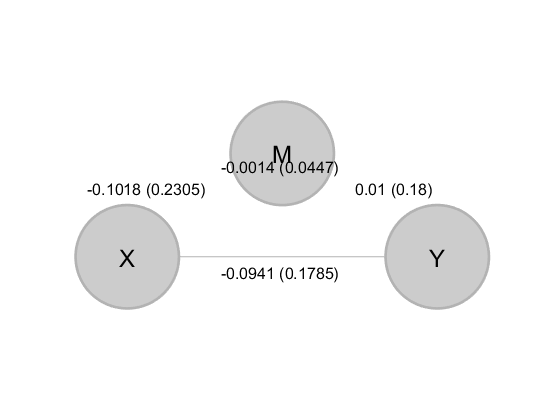

Mediation scatterplots:
Replications:   1
Covariates controlled for in all regressions:   0 predictors
Additional mediators controlled for in outcome predictions:   1 predictors


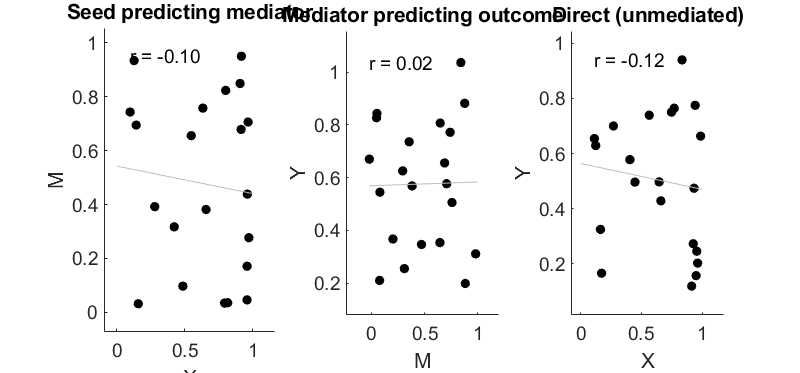


________________________________________

Single-level model
	a	b	c'	c	ab	
Coeff	-0.10	0.01	-0.09	-0.10	-0.00	
STE	0.23	0.18	0.18	0.17	0.04	
t (~N)	-0.44	0.08	-0.53	-0.55	-0.03	
Z	-0.44	0.08	-0.52	-0.54	-0.03	
p	0.6633	0.9372	0.6041	0.5866	0.9747	

________________________________________
Total time:   3 s


paths =    -0.1018    0.0141   -0.0941   -0.0955   -0.0014


stats = struct with fields:
           names: {'a'  'b'  'c''  'c'  'ab'}
            mean: [-0.1018 0.0141 -0.0941 -0.0955 -0.0014]
             ste: [0.2305 0.1768 0.1785 0.1729 0.0447]
               t: [-0.4419 0.0798 -0.5272 -0.5527 -0.0322]
              df: [20 19 19 20 19]
               p: [0.6633 0.9372 0.6041 0.5866 0.9747]
          residm: {[21×1 double]}
          residy: {[21×1 double]}
         residy2: {[21×1 double]}
           paths: [-0.1018 0.0141 -0.0941 -0.0955 -0.0014]
               w: [21×21 double]
        stdpaths: [0 0 0 0 0]
          abetas: {[2×1 double]}
          bbetas: {[2×1 double]}
         cpbetas: {[2×1 double]}
          cbetas: {[2×1 double]}
    inputOptions: [1×1 struct]
    analysisname: 'Single-level model'


[paths, stats] = mediation(x, y(:,1), m,'plots', 'verbose')

mod1=fitlm(x,m)

mod1 = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE        tStat       pValue  
                   _________    _______    ________    _________

    (Intercept)      0.44383    0.14679      3.0235    0.0069877
    x1             -0.031306    0.24877    -0.12584      0.90118


Number of observations: 21, Error degrees of freedom: 19
Root Mean Squared Error: 0.321
R-squared: 0.000833,  Adjusted R-Squared: -0.0518
F-statistic vs. constant model: 0.0158, p-value = 0.901

mod1.Coefficients("x1",:).Estimate

ans = -0.0313

mod1.Coefficients("x1",:).SE

mod2=fitlm(horzcat(x,m),y(:,1))

mod2 = Linear regression model:
    y ~ 1 + x1 + x2

Estimated Coefficients:
                   Estimate       SE        tStat        pValue  
                   _________    _______    ________    __________

    (Intercept)      0.61456    0.12582      4.8846    0.00011925
    x1               0.13442    0.17527     0.76696       0.45305
    x2             -0.029363    0.16157    -0.18174       0.85782


Number of observations: 21, Error degrees of freedom: 18
Root Mean Squared Error: 0.226
R-squared: 0.0338,  Adjusted R-Squared: -0.0735
F-statistic vs. constant model: 0.315, p-value = 0.734

mod2.Coefficients("x2",:).Estimate
mod2.Coefficients("x2",:).SE

fitlm(x,y(:,1))

ans = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate      SE        tStat       pValue  
                   ________    _______    _______    __________

    (Intercept)    0.60153     0.10071     5.9726    9.5173e-06
    x1             0.13534     0.17068    0.79296       0.43759


Number of observations: 21, Error degrees of freedom: 19
Root Mean Squared Error: 0.22
R-squared: 0.032,  Adjusted R-Squared: -0.0189
F-statistic vs. constant model: 0.629, p-value = 0.438

tic
mediationnn(x,y,m);
toc

Elapsed time is 41.063040 seconds.


x_gpu=gpuArray(x);
m_gpu=gpuArray(m);
y_gpu=gpuArray(y);
X=horzcat(x_gpu,m_gpu);
size(X)
size(y_gpu)
glm=cell(length(y),1);
tic
fit_model = @(Y) fitlm(X, Y{1}, 'linear');
% fit_model(y_gpu(:,1))

% arrayfun(fit_model, y_gpu);
glm = arrayfun(fit_model, mat2cell(y_gpu, size(y_gpu, 1), ones(1, size(y_gpu, 2))), 'UniformOutput', false);
% arrayfun(fit_model, y_gpu);
toc

tic
fit_model = @(Y) fitlm(X, Y, 'linear');
maki=fit_model(y_gpu)
maki.Coefficients.Estimate(2:3)

% arrayfun(fit_model, y_gpu);
% glm = arrayfun(fit_model, y_gpu, 'UniformOutput', false);
% arrayfun(fit_model, y_gpu);
toc

glm=cell(length(y),1);
tic
fit_model = @(Y) fitlm(horzcat(x,m), Y{1}, 'linear');
% arrayfun(fit_model, y_gpu);
glm = arrayfun(fit_model, mat2cell(y, size(y, 1), ones(1, size(y, 2))), 'UniformOutput', false);
% glm = arrayfun(fit_model, y, 'UniformOutput', false);
toc

Elapsed time is 71.959821 seconds.



arrayfun(@nyomasd,y,'UniformOutput', false)

x_gpu=gpuArray(x);
m=rand(21,10000);
m_gpu=gpuArray(m);
y_gpu=gpuArray(y);
size(x_gpu);
size(m_gpu);
% mat2cell(y_gpu, size(y_gpu, 1), ones(1, size(y_gpu, 2)));
tic
fit_model = @(M) fitlm(horzcat(x_gpu,M{1}), y_gpu, 'linear');
% arrayfun(fit_model, y_gpu);
cellversionofm=mat2cell(m_gpu, size(m_gpu, 1), ones(1, size(m_gpu, 2)));
models_cell = arrayfun(fit_model, cellversionofm, 'UniformOutput', false);
toc

mat2cell(m_gpu, size(m_gpu, 1), ones(1, size(m_gpu, 2)))

ans = 1×1000 cell array
  Columns 1 through 526

    {21×1 gpuArray}    {21×1 gpuArray}    {21×1 gpuArray}    {21×1 gpuArray}    {21×1 gpuArray}    {21×1 gpuArray}    {21×1 gpuArray}    {21×1 gpuArray}    {21×1 gpuArray}    {21×1 gpuArray}    {21×1 gpuArray}    {21×1 gpuArray}    {21×1 gpuArray}    {21×1 gpuArray}    {21×1 gpuArray}    {21×1 gpuArray}    {21×1 gpuArray}    {21×1 gpuArray}    {21×1 gpuArray}    {21×1 gpuArray}    {21×1 gpuArray}    {21×1 gpuArray}    {21×1 gpuArray}    {21×1 gpuArray}    {21×1 gpuArray}    {21×1 gpuArray}    {21×1 gpuArray}    {21×1 gpuArray}    {21×1 gpuArray}    {21×1 gpuArray}    {21×1 gpuArray}    {21×1 gpuArray}    {21×1 gpuArray}    {21×1 gpuArray}    {21×1 gpuArray}    {21×1 gpuArray}    {21×1 gpuArray}    {21×1 gpuArray}    {21×1 gpuArray}    {21×1 gpuArray}    {21×1 gpuArray}    {21×1 gpuArray}    {21×1 gpuArray}    {21×1 gpuArray}    {21×1 gpuArray}    {21×1 gpuArray}    {21×1 gpuArray}    {21×1 gpuArray}    {21×1 gpuArray}    {21×1 gpuArray} 

Copmare the timing of for and parfor:

tic
x=rand(21,1);
m=rand(21,10000);
y=rand(21,1);
n_voxels=length(m);
toc

Elapsed time is 0.008252 seconds.


a_est=NaN(1,n_voxels);
a_est_se=NaN(1,n_voxels);
b_est=NaN(1,n_voxels);
b_est_se=NaN(1,n_voxels);

tic
for voxels=1:n_voxels
            %mediation analysis with rating as the outcome
    mod1=fitlm(x,m(:,voxels));
    a_est(voxels)=mod1.Coefficients("x1",:).Estimate;
    a_est_se(voxels)=mod1.Coefficients("x1",:).SE;

    mod2=fitlm(horzcat(x,m(:,voxels)),y);
    b_est(voxels)=mod2.Coefficients("x2",:).Estimate;
    b_est_se(voxels)=mod2.Coefficients("x2",:).SE;
end
toc

Elapsed time is 112.079858 seconds.


a_est=NaN(1,n_voxels);
a_est_se=NaN(1,n_voxels);
b_est=NaN(1,n_voxels);
b_est_se=NaN(1,n_voxels);

tic
parfor voxels=1:n_voxels
            %mediation analysis with rating as the outcome
    mod1=fitlm(x,m(:,voxels));
    a_est(voxels)=mod1.Coefficients("x1",:).Estimate;
    a_est_se(voxels)=mod1.Coefficients("x1",:).SE;

    mod2=fitlm(horzcat(x,m(:,voxels)),y);
    b_est(voxels)=mod2.Coefficients("x2",:).Estimate;
    b_est_se(voxels)=mod2.Coefficients("x2",:).SE;
end
toc

Elapsed time is 30.396075 seconds.


varratio=(sqrt(a_est_se)./sqrt(b_est_se));
Istand=a_est.*b_est.*varratio

Istand =    -0.0823   -0.0011    0.1034    0.0005    0.0055    0.0338   -0.0797    0.0277   -0.0246   -0.0004    0.0033    0.1924   -0.0356    0.0021   -0.1038    0.1398   -0.0013    0.0074   -0.0015    0.0030   -0.0262    0.0523    0.0492   -0.0391    0.0566    0.0000    0.0049    0.0775   -0.0385   -0.0004   -0.1103   -0.0613    0.0410   -0.0000    0.0030    0.0746   -0.0057   -0.0137   -0.0009    0.0463   -0.0239    0.0009   -0.0546    0.0689   -0.0098   -0.0180    0.0821   -0.0097   -0.0166   -0.0139


% fit_model = @(Y) fitlm(x_gpu, Y{1}, 'linear');
se_ab=sqrt((a_est.^2.*a_est_se.^2)+(b_est.^2.*b_est_se.^2));
se_stand_sobel=varratio.*se_ab

se_stand_sobel =     0.1022    0.0199    0.1160    0.0254    0.0270    0.0610    0.1019    0.1031    0.0508    0.0263    0.0763    0.1481    0.0749    0.0166    0.1150    0.1240    0.0689    0.0864    0.0187    0.0223    0.0530    0.1229    0.0940    0.0730    0.1023    0.0135    0.0364    0.1109    0.1127    0.0077    0.1121    0.1251    0.1259    0.0089    0.0453    0.0997    0.0735    0.1328    0.0237    0.0871    0.0767    0.0754    0.1091    0.0913    0.0326    0.0517    0.1102    0.0441    0.0592    0.0649


max(Istand)

ans = 0.4712

m=5;
a_est(m).*b_est(m).*(sqrt(a_est_se(m))./sqrt(b_est_se(m)))

ans = 0.0055

for studyrank=1:26
    if ~isempty(stats(studyrank).delta)
        fprintf('%s\n',df.study_ID{studyrank});
        
        brainactivity_m=stats(studyrank).delta;
        [nsubj ~]=size(brainactivity_m);
        maki=sum(isnan(brainactivity_m),1);
        fprintf('Percentage of missin datapoint %f\n', max(maki)/nsubj*100);
        fprintf('number of missing subjects%i\n:',max(maki));
    end
end

function glm=mediationnn(x,y,m)
    glm=cell(length(y),1);
    X=horzcat(x,m);
    for jjj=1:length(y)
    Y=y(:,jjj);
    glm{jjj}=fitlm(X,Y);
    end

end
function kk=nyomasd(y)
    x=rand(21,1);
    k=fitlm(x,y);
    kk=k.Coefficients.Estimate(2);
end